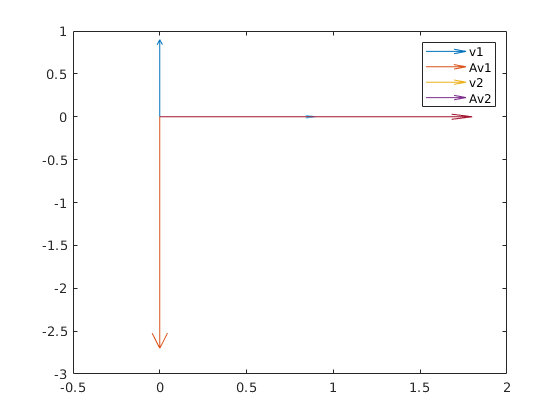

A = [2 0; 0 -3];
v1 = [1; 0];
v2 = [0; 1];

Av1 = A*v1;
Av2 = A*v2;

hold on
quiver(0, 0, v1(1), v1(2));
quiver(0, 0, Av1(1), Av1(2));
quiver(0, 0, v2(1), v2(2));
quiver(0, 0, Av2(1), Av2(2));

legend('v1', 'Av1', 'v2', 'Av2')

hold off

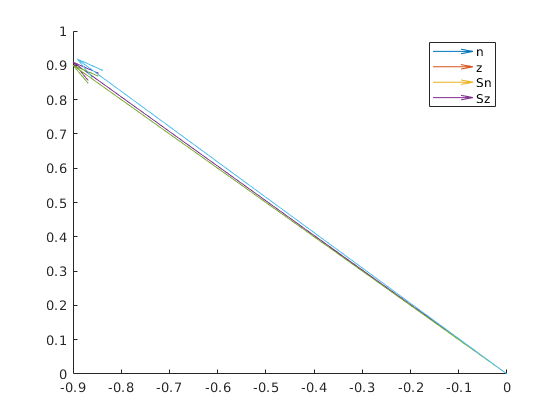

n = [-1; 1];
z = [-1; 1.01];
S = [2 1; 1 2];

Sn = S*n;
Sz = S*z;

hold on
quiver(0, 0, n(1), n(2));
quiver(0, 0, z(1), z(2));
quiver(0, 0, Sn(1), Sn(2));
quiver(0, 0, Sz(1), Sz(2));

legend('n', 'z', 'Sn', 'Sz')
hold off

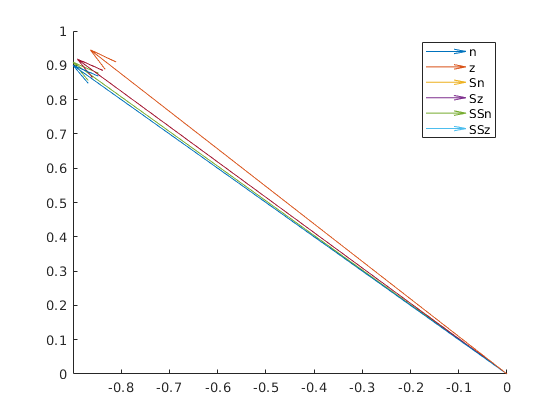

n = [-1; 1];
z = [-1; 1.01];
S = [2 1; 1 2];

Sn = S*n;
Sz = S*z;
SSn = S*S*n;
SSz = S*S*z;

hold on
quiver(0, 0, n(1), n(2));
quiver(0, 0, z(1), z(2));
quiver(0, 0, Sn(1), Sn(2));
quiver(0, 0, Sz(1), Sz(2));
quiver(0, 0, SSn(1), SSn(2));
quiver(0, 0, SSz(1), SSz(2));

legend('n', 'z', 'Sn', 'Sz', 'SSn', 'SSz')
hold off

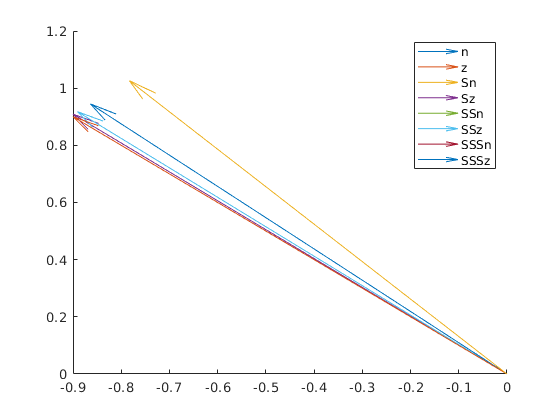

n = [-1; 1];
z = [-1; 1.01];
S = [2 1; 1 2];

Sn = S*n;
Sz = S*z;
SSn = S*S*n;
SSz = S*S*z;
SSSn = S*S*S*n;
SSSz = S*S*S*z;

hold on
quiver(0, 0, n(1), n(2));
quiver(0, 0, z(1), z(2));
quiver(0, 0, Sn(1), Sn(2));
quiver(0, 0, Sz(1), Sz(2));
quiver(0, 0, SSn(1), SSn(2));
quiver(0, 0, SSz(1), SSz(2));
quiver(0, 0, SSSn(1), SSSn(2));
quiver(0, 0, SSSz(1), SSSz(2));

legend('n', 'z', 'Sn', 'Sz', 'SSn', 'SSz', 'SSSn', 'SSSz')
hold off

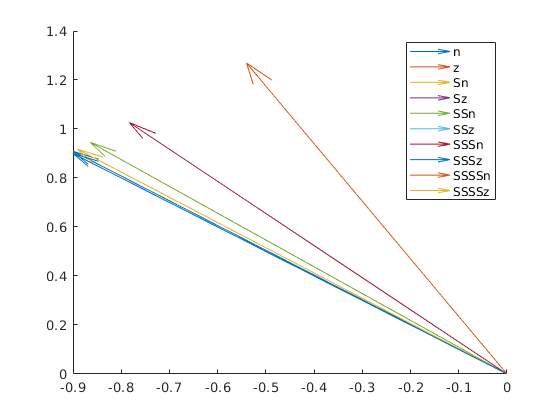

n = [-1; 1];
z = [-1; 1.01];
S = [2 1; 1 2];

Sn = S*n;
Sz = S*z;
SSn = S*S*n;
SSz = S*S*z;
SSSn = S*S*S*n;
SSSz = S*S*S*z;
SSSSn = S*S*S*S*n;
SSSSz = S*S*S*S*z;

hold on
quiver(0, 0, n(1), n(2));
quiver(0, 0, z(1), z(2));
quiver(0, 0, Sn(1), Sn(2));
quiver(0, 0, Sz(1), Sz(2));
quiver(0, 0, SSn(1), SSn(2));
quiver(0, 0, SSz(1), SSz(2));
quiver(0, 0, SSSn(1), SSSn(2));
quiver(0, 0, SSSz(1), SSSz(2));
quiver(0, 0, SSSSn(1), SSSSn(2));
quiver(0, 0, SSSSz(1), SSSSz(2));

legend('n', 'z', 'Sn', 'Sz', 'SSn', 'SSz', 'SSSn', 'SSSz', 'SSSSn', 'SSSSz')
hold off

A = randn(3, 3)

A =     0.5377    0.8622   -0.4336
    1.8339    0.3188    0.3426
   -2.2588   -1.3077    3.5784


eig(A)

ans =     3.8142
   -0.8472
    1.4678


trace(A)

ans = 4.4348

det(A)

ans = -4.7434

B = A' * A

B =     8.7546    4.0020   -7.6878
    4.0020    2.5550   -4.9440
   -7.6878   -4.9440   13.1103


[v, lambda] = eig(B)

v =     0.2562    0.7781   -0.5735
   -0.9432    0.0716   -0.3243
   -0.2113    0.6240    0.7523


lambda =     0.3605         0         0
         0    2.9572         0
         0         0   21.1022


clear
load('temps_bos_sp_dc.mat')
b_adj = b - mean(b);
s_adj = s - mean(s);
w_adj = w - mean(w);

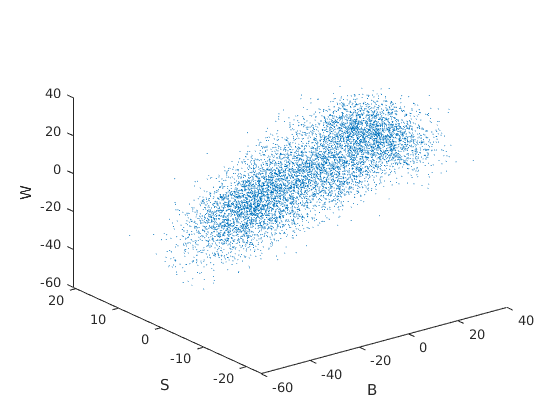

plot3(b_adj, s_adj, w_adj, '.', 'MarkerSize', 0.1);
xlabel('B')
ylabel('S')
zlabel('W')

A = 1/sqrt(length(b)-1) * [b_adj s_adj w_adj];
C = A' * A;
[v, lambda] = eigs(C)

v =     0.6994    0.1233   -0.7041
   -0.1516    0.9882    0.0225
    0.6985    0.0910    0.7098


lambda =   566.3086         0         0
         0   27.0811         0
         0         0   15.1269


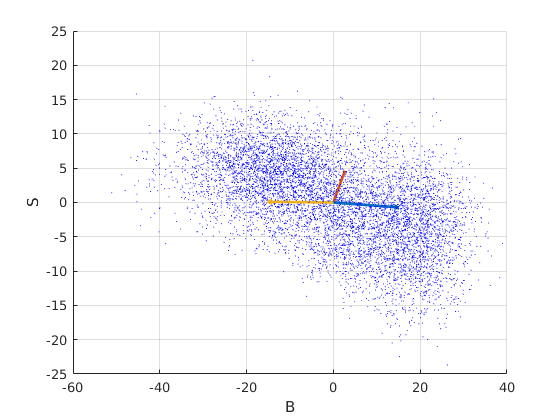

clf
hold on
grid on
v_adj = v.*sqrt(diag(lambda));
quiver3(0, 0, 0, v_adj(1, 1), v_adj(2, 1), v_adj(3, 1), 'LineWidth', 2)
quiver3(0, 0, 0, v_adj(1, 2), v_adj(2, 2), v_adj(3, 2), 'LineWidth', 2)
quiver3(0, 0, 0, v_adj(1, 3), v_adj(2, 3), v_adj(3, 3), 'LineWidth', 2)
plot3(b_adj, s_adj, w_adj, 'b.', 'MarkerSize', 0.1);
xlabel('B')
ylabel('S')
zlabel('W')